% Reset workspace
clear all ; close all

% Loading data
load('A2Data.mat')

## Part 1: Design an OFDM System 

- **Application:** Broadband connectivity in an urban environment.

- **Operating Spectrum:** Centered around 24 GHz.

- **Available Bandwidth:** 200 MHz.

- **Channel Conditions:** Subject to multipath fading resulting in a noticeable delay spread.

### 1.1 Design your OFDM system using the above information and the following system parameters.

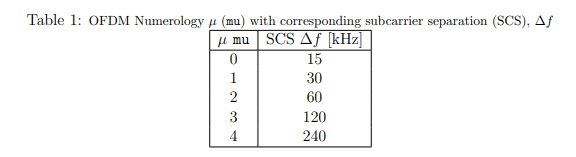

Using the numerology parameter µ (mu) provided to your group from the data generated in the workspace preparation section, determine the subcarrier spacing for your system. In your report, create a table listing the following OFDM parameters for your system: 

- **OFDM symbol duration (T) without the guard interval; **

- **guard interval duration (Tg), assuming that the guard interval is 7% of the OFDM symbol duration;**

- **  total OFDM symbol duration (Ts); **

- ** sample duration (Tsample), assuming an IFFT/FFT size of 4096; **

- **total occupied bandwidth of the system if the number of data-carrying active subcarriers cannot be greater than 3300;**

- ** maximum number of resource blocks your system can support, where one resource block is 12 subcarriers across 14 OFDM symbols. **

(Our groups value for $\mu =4$, thus we use the following subcarrier sepration $\nabla f=240\textrm{kHz}$

% SCS
delta_f = 240e3;

% OFDM Symbol duration 
T = 1/delta_f;

% Guard interval duration 
T_g = T * 0.07;

% Total OFDM symbol duration
T_s = T + T_g;

% sample duration (Tsample), assuming an IFFT/FFT size of 4096
N = 4096;
T_sample = T/N; 

% 

### 1.2 Create a table listing the data rates of the system for the following modulation schemes:

- **16-QAM**

- **64-QAM**

- **256-QAM**

- **1024-QAM**

 Assume that 10% of the resources are allocated for overhead, including control and other signalling. Plot a graph of modulation order versus data rate. On the same graph, plot the useful information throughput versus modulation order when the data is encoded with a 3/4 LDPC code. Discuss your observations. Interpretation requirement: Your discussion must explain the trade-off between higher modulation order, higher data rate, and reduced robustness to noise and fading.

M = [16,64,256,1024]

M =           16          64         256        1024



Data_rate_tot = ( N * log2(M) )/ T_sample

Data_rate_tot = 1.0e+13 *

    1.6106    2.4159    3.2212    4.0265


Data_rate_net = Data_rate_tot * 0.9

Data_rate_net = 1.0e+13 *

    1.4496    2.1743    2.8991    3.6239


Info_rate = 0.75 * Data_rate_net